# Basket

Use MATLAB with Python to play with NBA data

**Resources**

- [https://github.com/swar/nba_api](https://github.com/swar/nba_api) 

### Players

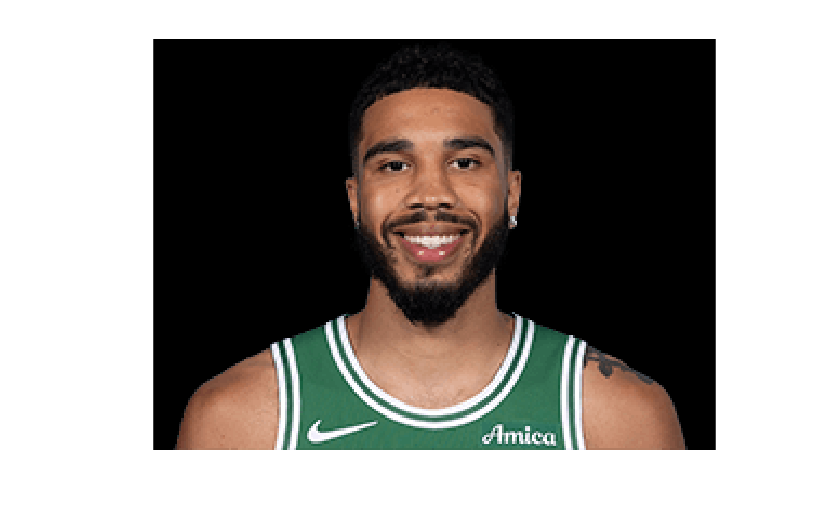

player_id = 1628369; % jayson tatum
image_url = "https://ak-static.cms.nba.com/wp-content/uploads/headshots/nba/latest/260x190/"+player_id+".png";
[im, cmap] = imread(image_url);
imshow(im,cmap)

career = py.nba_api.stats.endpoints.playercareerstats.PlayerCareerStats(player_id="203076");
c = career.get_data_frames();
table(c{1})

ans = 15×27 table
    PLAYER_ID    SEASON_ID    LEAGUE_ID     TEAM_ID      TEAM_ABBREVIATION    PLAYER_AGE    GP    GS    MIN     FGM    FGA     FG_PCT    FG3M    FG3A    FG3_PCT    FTM    FTA    FT_PCT    OREB    DREB    REB    AST    STL    BLK    TOV    PF     PTS 
    _________    _________    _________    __________    _________________    __________    __    __    ____    

### Teams

% get_teams returns a list of 30 dictionaries, each an NBA team.
nba_teams = py.nba_api.stats.static.teams.get_teams()

nba_teams =   Python list with values:

    [{'id': 1610612737, 'full_name': 'Atlanta Hawks', 'abbreviation': 'ATL', 'nickname': 'Hawks', 'city': 'Atlanta', 'state': 'Georgia', 'year_founded': 1949}, {'id': 1610612738, 'full_name': 'Boston Celtics', 'abbreviation': 'BOS', 'nickname': 'Celtics', 'city': 'Boston', 'state': 'Massachusetts', 'year_founded': 1946}, {'id': 1610612739, 'full_name': 'Cleveland Cavaliers', 'abbreviation': 'CLE', 'nickname': 'Cavaliers', 'city': 'Cleveland', 'state': 'Ohio', 'year_founded': 1970}, {'id': 1610612740, 'full_name': 'New Orleans Pelicans', 'abbreviation': 'NOP', 'nickname': 'Pelicans', 'city': 'New Orleans', 'state': 'Louisiana', 'year_founded': 2002}, {'id': 1610612741, 'full_name': 'Chicago Bulls', 'abbreviation': 'CHI', 'nickname': 'Bulls', 'city': 'Chicago', 'state': 'Illinois', 'year_founded': 1966}, {'id': 1610612742, 'full_name': 'Dallas Mavericks', 'abbreviation': 'DAL', 'nic

T = table(py.pandas.DataFrame(nba_teams))

T = 30×7 table
        id               full_name            abbreviation       nickname            city              state         year_founded
    __________    ________________________    ____________    ______________    ______________    _______________    ____________

    1610612737    "Atlanta Hawks"                "ATL"        "Hawks"           "Atlanta"         "Georgia"              1949    
    1610612738    "Boston Celtics"               "BOS"        "Celtics"         "Boston"          "Massachusetts"        1946    
    1610612739    "Cleveland Cavaliers"          "CLE"        "Cavaliers"       "Cleveland"       "Ohio"                 1970    
    1610612740    "New Orleans Pelicans"         "NOP"        "Pelicans"        "New Orleans"   

teams = T.abbreviation;
team = teams(1);
team_id = T{teams == team,"id"}

team_id = int64
1610612737

% team_id = 1610612738 % celtics https://www.nba.com/stats/team/1610612738
game_log = py.nba_api.stats.endpoints.teamgamelog.TeamGameLog(team_id=team_id, season='2024-25').get_data_frames();
table(game_log{1})

ans = 82×27 table
     Team_ID        Game_ID         GAME_DATE          MATCHUP       WL     W     L     W_PCT    MIN    FGM    FGA    FG_PCT    FG3M    FG3A    FG3_PCT    FTM    FTA    FT_PCT    OREB    DREB    REB    AST    STL    BLK    TOV    PF    PTS
    __________    ____________    ______________    _____________    ___    __    __    _____    ___    ___    <s

### Games

% Python code input
pycode = [...
"from nba_api.stats.endpoints import leaguegamefinder",...
"league_game_finder = leaguegamefinder.LeagueGameFinder(league_id_nullable='00', season_nullable='2024-25')",...
"games = league_game_finder.get_data_frames()[0]"...
];

try
    [games2] = pyrun(pycode, ...
         [ "games" ])
catch ME
    % Clear temporary variables from workspace and from Python
    clear pycode;
    rethrow(ME)
end

games2 =   Python DataFrame with properties:

          T: [1×1 py.pandas.core.frame.DataFrame]
         at: [1×1 py.pandas.core.indexing._AtIndexer]
      attrs: [1×1 py.dict]
       axes: [1×2 py.list]
    columns: [1×1 py.pandas.core.indexes.base.Index]
     dtypes: [1×1 py.pandas.core.series.Series]
      empty: 0
      flags: [1×1 py.pandas.core.flags.Flags]
        iat: [1×1 py.pandas.core.indexing._iAtIndexer]
       iloc: [1×1 py.pandas.core.indexing._iLocIndexer]
      index: [1×1 py.pandas.core.indexes.range.RangeIndex]
        loc: [1×1 py.pandas.core.indexing._LocIndexer]
       ndim: [1×1 py.int]
      shape: [1×2 py.tuple]
       size: [1×1 py.numpy.int32]
      style: [1×1 py.pandas.io.formats.style.Styler]
     values: [1×1 py.numpy.ndarray]

         SEASON_ID     TEAM_ID TEAM_ABBREVIATION  ... TOV  PF PLUS_MINUS
    0        42024  1610612760               OKC  ...  13  20       


% Clear temporary variables from workspace and from Python
clear pycode;
table(games2)

ans = 2792×28 table
    SEASON_ID     TEAM_ID      TEAM_ABBREVIATION           TEAM_NAME              GAME_ID        GAME_DATE         MATCHUP       WL     MIN    PTS    FGM    FGA    FG_PCT    FG3M    FG3A    FG3_PCT    FTM    FTA    FT_PCT    OREB    DREB    REB    AST    STL    BLK    TOV    PF    PLUS_MINUS
    _________    __________    _________________    ________________________    ____________    ____________ 